# Machine Learning, AI tools, and Analysis

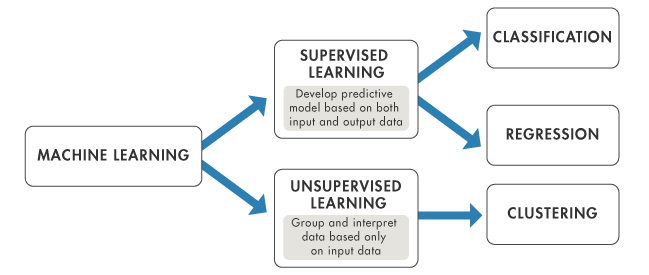

## Part A: Introduction

Imagine teaching a computer to learn from examples, just like how you learn from practice problems in math class. That's what machine learning is about, and MATLAB makes it easy to explore. It's like having a virtual lab where you can play with data and teach your computer to recognize patterns or make predictions without telling it exactly what to do. With MATLAB, you can create cool projects like predicting future stock prices or identifying handwritten digits. It's not just about coding; it's about teaching computers to think a bit like us. So, if you're curious about how computers learn and want to dive into the world of AI, MATLAB is your playground!

## Part B: What is a KNN model

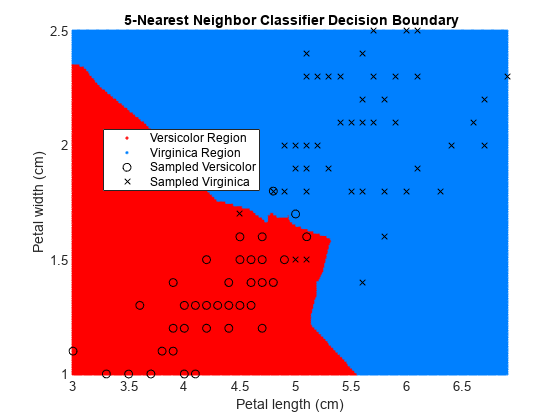

Imagine you’re a music enthusiast building a recommendation system. The K-Nearest Neighbors (KNN) model is like having a group of friends who help you make recommendations based on the countless songs they've listened to. In the KNN model, when you give it a new data point, it looks at the 'nearest neighbors' – the data points closest to it – and makes a decision based on what those neighbors are like.  For instance, if you’re trying to classify a new genre or artist, KNN analyzes nearby songs in your dataset and predicts the genre or artist based on what those musical neighbors are like. It’s a straightforward approach that adapts well to various problems like classification, regression, and recommendation systems. Plus, it doesn't require training beforehand; it learns as it goes.

Next, we'll dive into coding a sports related KNN model together. We'll show you how to use MATLAB to implement KNN, step by step, so you can see firsthand how this powerful technique works in action.

## Part C: KNN model example

### Step 1: Gather & Visualize Data

All models require data, so first we going to review how use the `readtable` function and dot notation to import data stored in a spreadsheet or text file. You can use the `readtable` function to import tabular data from a spreadsheet or text file and store the result as a table. The code below shows how to import the data from the spreadsheet `myfile.xlsx` and store it in a table variable called `data`.

% data = readtable("myfile.xlsx");

Once you have data in a variable, you can use dot notation to refer to any individual variable within a table. The first line of code extracts the variable `Xdata` from the table `mytable` and stores the result in a new variable named `x`. Similarly, the second line of code extracts the variable `Ydata` into `y`.

% x = mytable.Xdata;
% y = mytable.Ydata;

Alright, now that we all remember how to extract data from files let's start working with the xlsx file RacerStartingPositionFinalPosition.xlsx which contains a table of 56 starting and final positions for 5 drivers from 13 races in the 2022 Formula 1 season. The table has three variables: StartingPosition, FinalPosition, and Driver.

**Now You Try It!**

**Instructions: **Plot the extracted features from RacerStartingPositionFinalPosition.xlsx, by using the `scatter` function, with StartingPosition on the horizontal axis and FinalPosition on the vertical axis

clc; clear;
% Read the table data from the Excel file "RacerStartingPositionFinalPosition.xlsx"
% and store it in the variable RacerTestData.
%%% YOUR CODE GOES HERE %%%

% Create a scatter plot of the data, with the StartingPosition column on the x-axis
% and the FinalPosition column on the y-axis.
%%% YOUR CODE GOES HERE %%%
 

One issue with the plot above is that we can't distinguish the 5 drivers in the data set (Verstappen, Hamilton, Norris, Tsunoda, and Ricciardo ). The `gscatter` function makes a grouped scatter plot: a scatter plot where the points are colored according to a grouping variable.

Let's use the `gscatter` function to create the same scatter plot as before, but grouped by the driver.

% Creates a grouped scatter plot of the data from the RacerTestData table.
% The StartingPosition column is used for the x-axis values,
% the FinalPosition column is used for the y-axis values,
% and the Driver column is used to group the data points by different drivers.
gscatter(RacerTestData.StartingPosition, RacerTestData.FinalPosition, RacerTestData.Driver)
 

Good job! It appears the new scatter plot worked, allowing you to assess the drivers' performance based on their starting and final positions. However, distinguishing between multiple drivers remains challenging due to overlapping data points. Remember that it is crucial to fully understand the data you are working, so it is important to find the best way to represent it. 

To address the overlapping data, we need to use 3D scatter plot. Unlike 2D plots which only have two axes (x, y) a 3D plot has three axes (x, y, z). The images below shows two simple scatter plots, which both contain 15 data points. However, due to overlapping it appears that the 2D plot only has 5 data points. For this reason you need a 3D plot to get the full picture.

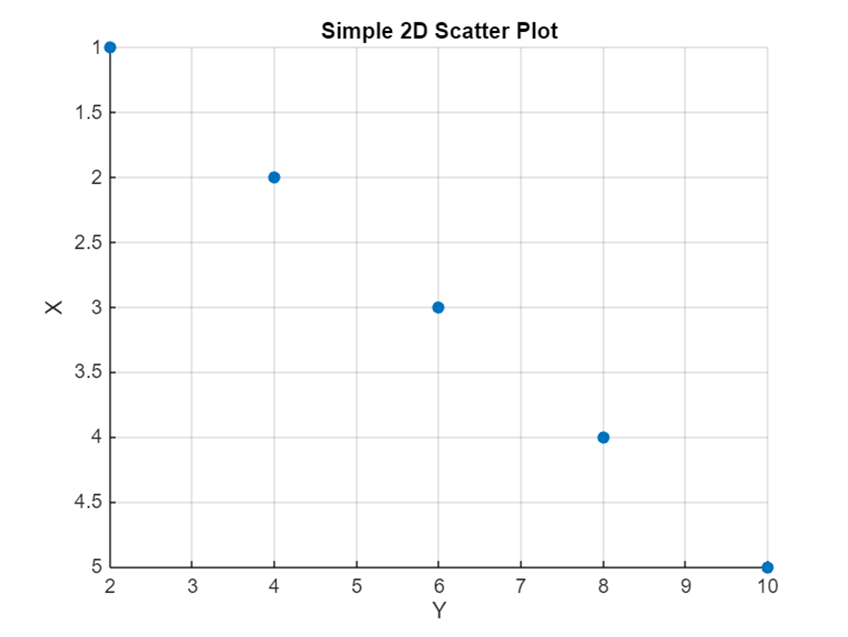       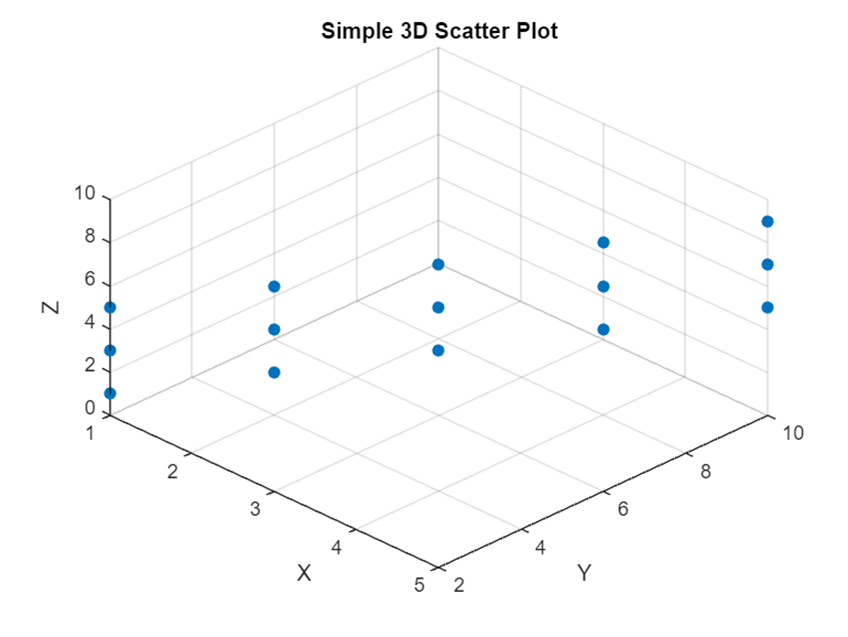

Below are step-by-step code and comments to guide you through the creation of a 3D plot for the driver data! The plot will use the same data as before, but it will now have an extra axis containing the names of the drivers. 

RacerTestData = readtable("RacerStartingPositionFinalPosition.xlsx");

% Extracts the 'Driver' column from the table RacerTestData as a categorical array
DriverNames = categorical(RacerTestData.Driver);

% Creates a 3D scatter plot
figure;

% variables for each axes, Size 36 for markers, color coded by Driver
scatter3(RacerTestData.StartingPosition,RacerTestData.FinalPosition, DriverNames, ...
    36, DriverNames, 'filled'); 

% Adds a title and label the axes
title('3D Scatter Plot of Starting Position, Final Position, and Driver');
xlabel('Starting Position');
ylabel('Final Position');
zlabel('Driver');

% Shows the plot
grid on;
view(45, 25) % Adjust the plot angle for better visibility

%Finally let's create a legend for the scatter plot
colormap(lines(length(categories(DriverNames))));
c = colorbar; % Create a colorbar
c.Ticks = 1:length(categories(DriverNames)); % Sets number of tick marks = number of drivers.
c.TickLabels = categories(DriverNames); % Label names of the drivers.
 

### Step 2: Fit the KNN Model

Now that we have successfully visualized the data we can begin to working with the kNN model. You can fit a kNN model by passing a table of data through the `fitcknn` function.

%mdl = fitcknn(data,"ResponseVariable");

The second input is the name of the response variable in the table (the class you want the model to predict). The output is a variable containing the fitted model.

**Now You Try It!**

**Instructions: **Fit a model to the data stored in RacerTestData by using the `fitcknn` function. The known classes are stored in the variable named Driver. Store the resulting model in a variable named `knnmodel`.

% Fit a k-nearest neighbors (KNN) classification model using the data in RacerTestData.
% The model predicts the 'Driver' based on the other variables in the table.
% The resulting model is stored in the variable knnmodel.
%%% YOUR CODE GOES HERE %%%
 

The `predict` function determines the predicted class of new observations.

%predClass = predict(model,newdata)

The inputs are the trained model and new observations. The output is a categorical array of the predicted class for each observation in `newdata`.

Typically, you must specify the new observations in the form of a table with the same predictor variables as were used to train the model. In this task, however, the model uses two numeric features (the starting position and the final position), so you can specify the observations as a numeric array with two columns.

Let's classify a racer with a starting position of 12 and a final position of 10 by using the `predict` function with the trained model `knnmodel`. Store the predictions in a variable named `predicted`. Provide the letter features as a two-element row vector.

% Uses the trained KNN model (knnmodel) to predict the driver for a new data point.
% The new data point has a starting position of 12 and a final position of 10.
% The predicted driver is stored in the variable predicted.
predicted = predict(knnmodel, [12, 10])
 

misclassrate = 0.3617

Another feature of the kNN model is that you can specify the value of *k* in the kNN model by setting the `"NumNeighbors"` option when calling `fitcknn`. 

%mdl = fitcknn(data,"ResponseVariable","NumNeighbors",10);

Adjusting the number of nearest neighbors the model utilizes can have an impact on the model's prediction, so lets rerun the model to see if the prediction changes. 

**Now You Try It!**

**Instructions: **Repeat the commands from the previous two tasks, but use the `"NumNeighbors"` option to change the number of neighbors in the model to 8.

% Fit a k-nearest neighbors (KNN) classification model
% using the data in RacerTestData.
% The number of neighbors to consider for the 
% KNN algorithm is set to 8.
%%% YOUR CODE GOES HERE %%%

% Use knnmodel to predict the driver for a new data point.
% The new data point has a starting position of 12 and
% a final position of 10.
%%% YOUR CODE GOES HERE %%%

 

### Step 3: Evaluate the Model

How good is the kNN model? You can use the model to make predictions, but how accurate are those predictions? Typically, you want to test the model by having it make predictions on observations for which you know the correct classification.

The file VerificationTestData.xlsx contains a table, that has the same variables as RacerTestData, including the known classes for the test observations. You can use the `predict` function to determine the predictions of the kNN model for the observations in `Verificationtestdata`, and then compare the predictions to the known classes to see how well the model performs on new data.

Let's classify the letters in the table `Verificationtestdata` by using the `predict` function with the trained model `knnmodel`. We will store the predictions in a variable named `predictions`.

% Fits a k-nearest neighbors (KNN) classification model using the data in RacerTestData.
% The model predicts the 'Driver' based on the other variables in the table.
% The number of neighbors to consider for the KNN algorithm is set to 8.
% The resulting model is stored in the variable knnmodel.
knnmodel = fitcknn(RacerTestData, "Driver", "NumNeighbors", 8);

% Reads the table data from the Excel file 'VerificationTestData.xlsx'
% and stores it in the variable VerificationTestData.
VerificationTestData = readtable('VerificationTestData.xlsx');

% Uses the trained KNN model (knnmodel) to predict the drivers for the new data points 
% in VerificationTestData. The predictions are stored in the variable predictions.
predictions = predict(knnmodel, VerificationTestData)
 

Now that we have made some predictions using our trained kNN model and we can compare them to the correct results stored in the variable `Verificationtestdata. `

To compare `predictions` to the known classes we can use the @isequal operator as shown in the code below. 

% Compares the predicted drivers with the actual drivers in VerificationTestData.
% cellfun applies the isequal function to each element in the predictions and VerificationTestData.Driver.
% The result is a logical array (true/false) indicating whether each prediction is correct.
iscorrect = cellfun(@isequal, predictions, VerificationTestData.Driver)
 

The logical array shows us which predictions that are correct by marking their position with the number `1`. To quantify the accuracy of our kNN model we can divide the number of correct predictions by the total number of predictions. 

**Try It!**

**Instructions: ** Calculate the accuracy of the model and store the result in a variable named `accuracy`. You can use the `sum` function to determine the number of correct predictions and the `numel` function to determine the total number of predictions.

% Calculate the accuracy of the predictions by dividing the number of correct predictions
% by the total number of predictions made.
% The variable 'iscorrect' contains a logical array indicating whether each prediction is correct.
% 'sum(iscorrect)' calculates the total number of correct predictions.
% 'numel(predictions)' calculates the total number of predictions made.
% The result is stored in the variable 'accuracy'.
%%% YOUR CODE GOES HERE %%%

 

Rather than accuracy (the proportion of correct predictions), a commonly used metric to evaluate a model is *misclassification rate* (the proportion of incorrect predictions).

To determine the misclassification rate we have to divide the number of wrong predictions by the total number of predictions made. 

In the code below, the variable `iswrong` contains a logical array indicating whether each prediction is incorrect. The line `sum(iswrong)` calculates the total number of wrong predictions and `numel(predictions) `calculates the total number of predictions made.

% The result is stored in the variable 'misclassrate'.
iswrong = ~cellfun(@isequal, predictions, VerificationTestData.Driver);
misclassrate = sum(iswrong) / numel(predictions)
 

Accuracy and misclassification rate give single values for the overall performance of the model, but it can be useful to see a more detailed breakdown of which classes the model confuses. A *confusion matrix* shows the number of observations for each combination of true and predicted class.

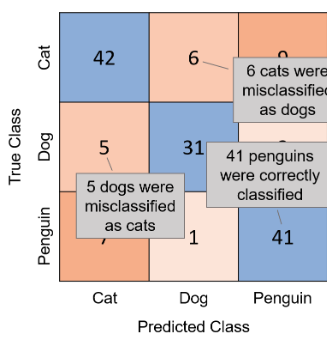

A confusion matrix is commonly visualized by shading the elements according to their value. Often the diagonal elements (the correct classifications) are shaded in one color and the other elements (the incorrect classifications) in another color. You can visualize a confusion matrix by using the `confusionchart` function.

%confusionchart(ytrue,ypred);

where `ytrue` is a vector of the known classes and `ypred` is a vector of the predicted classes.

**Now You Try It!**

**Instructions:  **Compare `predictions` to the known labels (stored in the variable `Character` in the table `testdata`) by using the `confusionchart` function.

% Generate a confusion chart to visualize the performance of the classifier.
% The confusion chart compares the actual drivers (ground truth) from VerificationTestData
% with the predicted drivers from the 'predictions' variable.
%%% YOUR CODE GOES HERE %%%

 